rbt = importrobot('universalUR5e.urdf','DataFormat','row');
ur5e = exampleHelperAddGripper(rbt);

ROSDeviceAddress = '192.168.132.128'; % IP address
username = 'user'; % User name
password = 'password'; % Password corresponds to user name

ROSFolder = '/opt/ros/noetic'; % ROS installation folder
WorkSpaceFolder = '~/ur_ws'; % UR ROS driver installation workspace folder location

device = rosdevice(ROSDeviceAddress,username,password);
device.ROSFolder = ROSFolder;

generateAndTransferLaunchScriptForUR5eSimGazebo(device,WorkSpaceFolder);

if ~isCoreRunning(device)
    w = strsplit(system(device,'who'));
    displayNum = cell2mat(w(2));

    system(device,['export SVGA_VGPU10=0; ' ...
        'export DISPLAY=' displayNum '.0; ' ...
        './launchURBinPicking.sh &']);
    pause(10);
end
gzinit(ROSDeviceAddress,14581);
rosshutdown;

Shutting down global node /matlab_global_node_65272 with NodeURI http://192.168.132.1:61088/ and MasterURI http://192.168.132.128:11311.


rosinit(ROSDeviceAddress);

Initializing global node /matlab_global_node_90276 with NodeURI http://192.168.132.1:61337/ and MasterURI http://192.168.132.128:11311.


pause(20);
% Create an instance to communicate with the simulated UR5e cobot
ur = universalrobot(ROSDeviceAddress,'RigidBodyTree',ur5e);

Using user-defined rigid body tree model.


% Send To home position
sendJointConfigurationAndWait(ur,homePosition,'EndTime',2);
pause(2);

% call ROS service for pause the Gazebo world
physicsClientPause = rossvcclient('gazebo/pause_physics');
call(physicsClientPause,'Timeout',3);

% Set states for table, bin and stand
gzmodel('set','bin_picking_stand','Position',[0 0 0.001],'Orientation',eul2quat([0,0,0]))

STATUS:  Succeed


MESSAGE:  Parameter set successfully.




pause(0.5);
gzmodel('set','pvc_tray','Position',[0.48 0 0.55],'Orientation',eul2quat([1.57 0 0]),"SelfCollide","off","IsStatic","on")

STATUS:  Succeed


MESSAGE:  Parameter set successfully.




pause(0.5);
gzlink('set','table_solid','link','Position',[0.17 0.68 0.4],'Orientation',eul2quat([0,0,0]));

STATUS:  Succeed


MESSAGE:  Parameter set successfully.




% call ROS service for un-pause the Gazebo world
physicsClientUnpause = rossvcclient('gazebo/unpause_physics');
call(physicsClientUnpause,'Timeout',3);

% create mesh
px1 = -0.20:0.12:0.24;
py1 = -0.12:0.11:0.12;

py1 = py1(randperm(length(py1)))+0.48;
px1 = px1(randperm(length(px1)));

temp = cell(length(px1),length(py1));

for i = 1:length(px1)
    for j = 1:length(py1)
        temp(i,j) = {[px1(i), py1(j)]};
    end
end

newPose = reshape(temp,[1,length(px1)*length(py1)]);

% get the list of the world models
modelList = gzmodel("list");

% list of the target objects (naming starts with part1, part2 etc.)
partList = modelList(contains(modelList,"part"));


ii=randperm(length(newPose));
b=newPose(ii);

% spawn the world
for i=1:length(partList)
    partGT = cell2mat(b(i));
    gzlink('set',partList(i),'link','Position',[partGT(2) partGT(1) 0.7],'Orientation',eul2quat([rand*pi*0.8,0,0]));
end

STATUS:  Succeed


MESSAGE:  Parameter set successfully.


STATUS:  Succeed


MESSAGE:  Parameter set successfully.


STATUS:  Succeed


MESSAGE:  Parameter set successfully.


STATUS:  Succeed


MESSAGE:  Parameter set successfully.


STATUS:  Succeed


MESSAGE:  Parameter set successfully.


STATUS:  Succeed


MESSAGE:  Parameter set successfully.




pause(3);

% semi-structure distribution constraint 
for i=1:length(partList)
    % Check if the part is not in the favourable orientation. Change the
    % orientation in this case
    partOrient = quat2eul(gzlink('get',partList(i),'link','Orientation'),"XYZ");
    if abs(partOrient(1)) > 0.01 || abs(partOrient(2)) > 0.01
        gzlink('set',partList(i),'link','Orientation',eul2quat([rand*pi*0.8,0,0]));
    end
end
pause(3);

rgbImgSub = rossubscriber('/camera/color/image_raw','DataFormat','struct');
subi = receive(rgbImgSub);
rgbImage = rosReadImage(subi,"PreserveStructureOnRead",true);

pointCloudSub = rossubscriber('/camera/depth/color/points','DataFormat','struct');
sub = receive(pointCloudSub);
ptCloud = rosReadXYZ(sub,"PreserveStructureOnRead",true);
ptCloud = pointCloud(ptCloud);

showPartialOutputs = true;

pretrained = load('trainedYOLOv4DetectorSimGazebo_cuboid.mat')

pretrained = struct with fields:
       detector: [1×1 yolov4ObjectDetector]
    elapsedTime: 91.4040
           info: [1×1 struct]


trainedYoloNet = pretrained.detector; %YOLOv4 network

[bboxes,scores,labels] = detectObjectsYoloNet(trainedYoloNet,rgbImage);

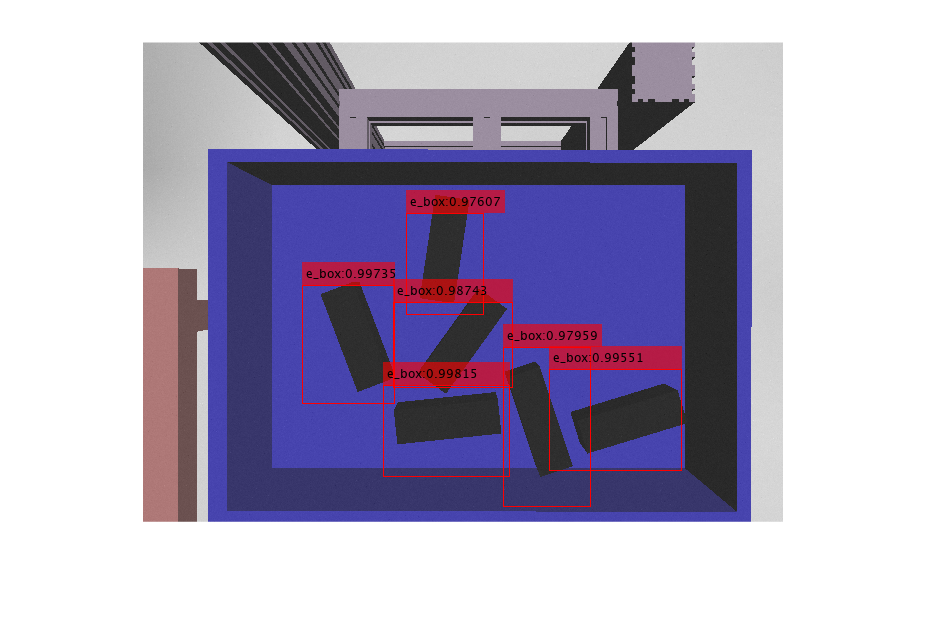

if(showPartialOutputs)
    % visualize the detected object bounding box
    annotatedImage = insertObjectAnnotation(im2uint8(rgbImage), 'Rectangle',...
        bboxes, string(labels)+":"+string(scores),'Color','r');
    figure, imshow(annotatedImage);
end

validIdx = scores > yoyloScoreTh;
bboxes = bboxes(validIdx, :);
scores = scores(validIdx);
labels = labels(validIdx);
numObjects = size(bboxes,1);

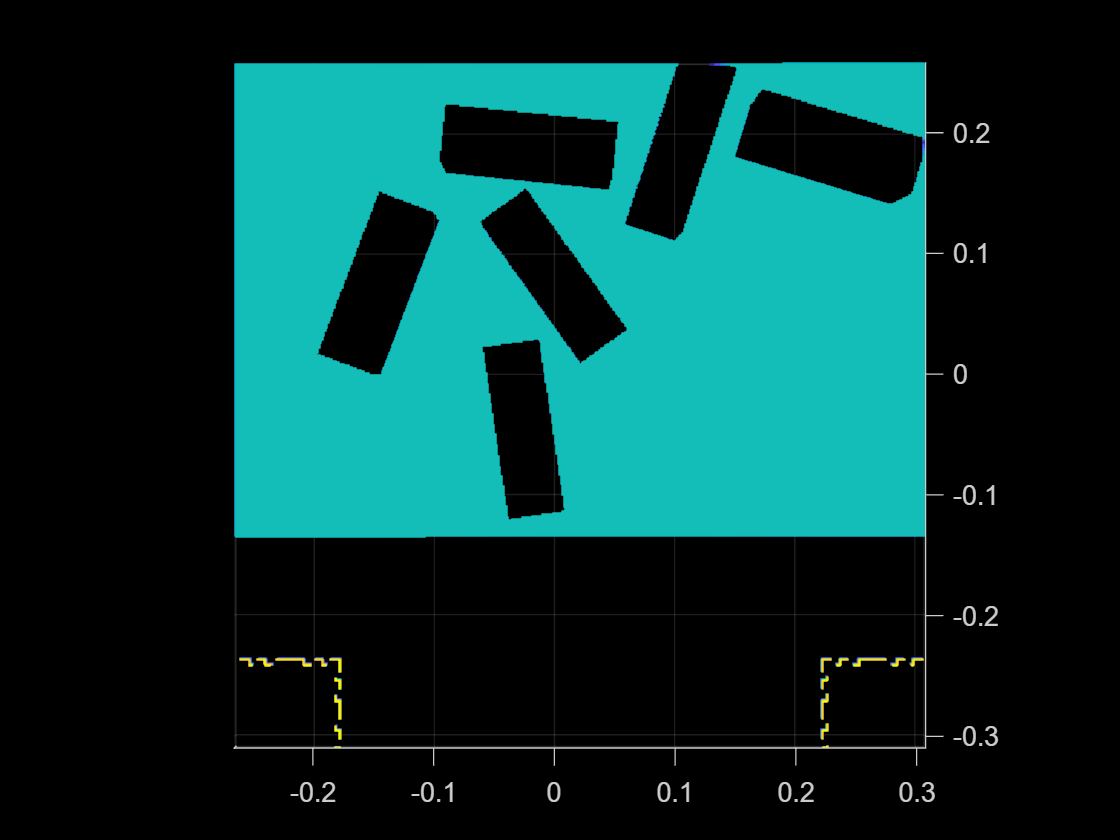

% Find plane and non-plane indices of the points from the point cloud
[param, planeIdx, nonPlaneIdx] = pcfitplane(ptCloud, PlanrThickness, normalvector, maxPlaneTilt);

% Create new point cloud by selecting only plane indices from original
% point cloud
plane = select(ptCloud, planeIdx);

% Create new point cloud by selecting non-plane indices from original
% point cloud
nonPlane = select(ptCloud, nonPlaneIdx);

if(showPartialOutputs)
    figure,pcshow(plane,'ViewPlane','XY');axis on;
end


% Create non-plane mask of the same size as raw input image
[m,n,~] = size(rgbImage);
nonPlaneMask = zeros(m,n);
nonPlaneMask =nonPlaneMask(:);
nonPlaneMask(nonPlaneIdx)= 1;

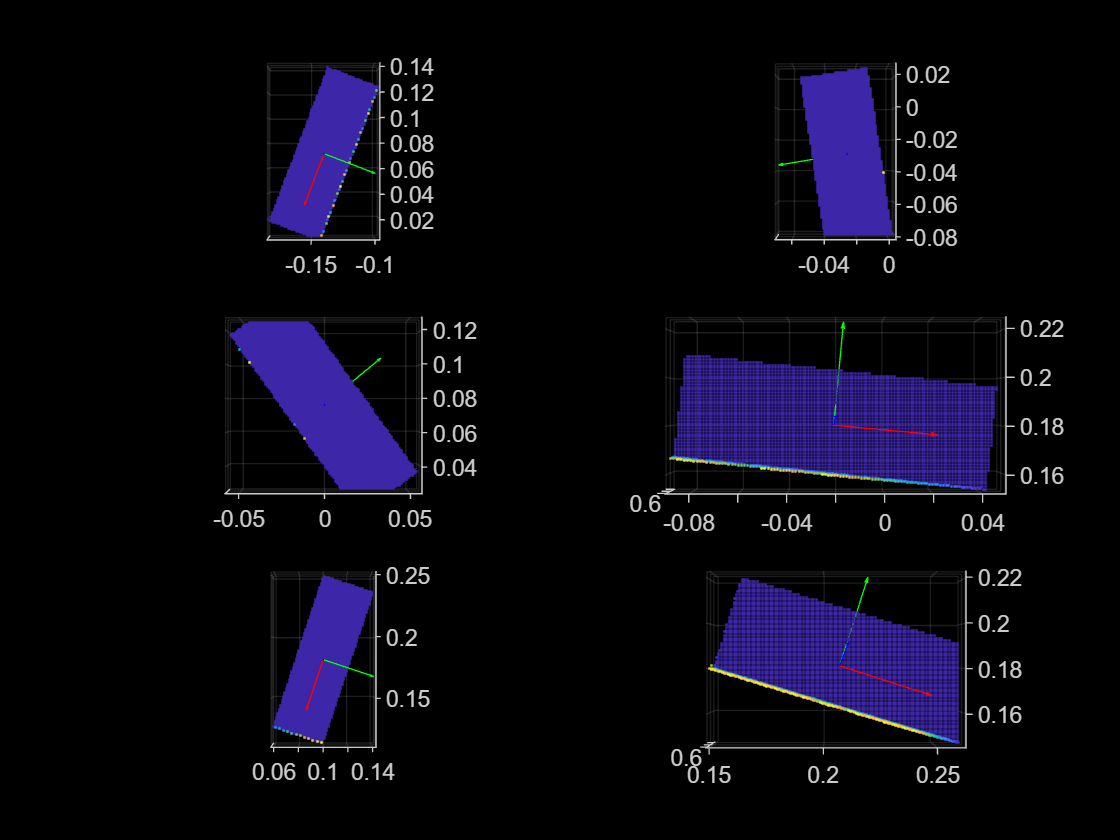

% Compute the object pose from YOLO output
[xyz,theta,ptCloudVector,ptCloudParameterVector] = findObjectPoses(ptCloud,rgbImage, bboxes, gridDownsample, nonPlaneMask);

% Visualize computed PCA
if(showPartialOutputs)
    figure;
    for idx = 1: numObjects
        U = ptCloudParameterVector{idx}.UVW(:,1);
        V = ptCloudParameterVector{idx}.UVW(:,2);
        W = ptCloudParameterVector{idx}.UVW(:,3);
        centerOfObject = ptCloudParameterVector{idx}.centroid;
        nexttile;
        pcshow(ptCloudVector{idx},'ViewPlane','XY');
        hold on;
        quiver3(centerOfObject(1), centerOfObject(2), centerOfObject(3), U(1), V(1), W(1), 'r');
        quiver3(centerOfObject(1), centerOfObject(2), centerOfObject(3), U(2), V(2), W(2), 'g');
        quiver3(centerOfObject(1), centerOfObject(2), centerOfObject(3), U(3), V(3), W(3), 'b');
        hold off;
    end
end

thetaNew = zeros(numObjects,1);
for idx = 1:numObjects
    U = ptCloudParameterVector{idx}.UVW(:,1);
    V = ptCloudParameterVector{idx}.UVW(:,2);
    W = ptCloudParameterVector{idx}.UVW(:,3);
    majorAxis = [U(1), V(1), W(1)];
    majorAxis = (rotationFromRobotToCam*majorAxis')';
    %This calculates the angle between the positive y axis ([ 0 1 0]) and the major axis of the object in an anti-clockwise direction
    thetaNew(idx) = atan2d(dot([0 0 1],cross([  0 1 0],majorAxis)),dot([ 0 1 0],majorAxis));
    if (thetaNew(idx)<0)
        thetaNew(idx) = 180 + thetaNew(idx);
    end
end

partGT = zeros(numObjects,4);

for i=1:length(ptCloudParameterVector)
    partGT(i,1:3) = rotationFromRobotToCam*xyz(i,:)' + posDepthCam';
    partGT(i,4) = thetaNew(i);
end

plannerFunctionToRun = "MEX";

ik = inverseKinematics('RigidBodyTree',ur5e);
ik.SolverParameters.AllowRandomRestart = false;
ik.SolverParameters.GradientTolerance = 1e-13;
ik.SolverParameters.MaxTime = 5;

% Set weight matrix
weights = [1 1 1 1 1 1];

targetPoseAngleAtApproach = [0 pi 0];

for p = 1:numObjects
    disp("Starting computation for approach trajectory");
    %%%%%% Approach trajectory %%%%%%
    % Select part to pick basesd on selection algorithm
    [refPose,partID] = exampleHelperSelectPartForMEXPlanner(partGT,binCenterPosition);

    % Compute the target pose for the approach
    targetPoseXYZ = refPose;
    targetPose = trvec2tform(targetPoseXYZ)*eul2tform(targetPoseAngleAtApproach,"ZYX");

    % Compute final configuration for the approach using inverse kinematics
    initialGuess = homePosition;
    [configSoln,solnInfo] = ik(ur5e.BodyNames{end},targetPose,weights,initialGuess);

    % Check that the computed final pose satisfies the position thresholds. If
    % the condition does not satisfied then compute IK with updated
    % paramters as shown below
    if solnInfo.PoseErrorNorm > poseThr
        ik.SolverParameters.MaxTime = 10;
        ik.SolverParameters.AllowRandomRestart = true;

        [configSoln,solnInfo] = ik(ur5e.BodyNames{end},targetPose,weights,initialGuess);

        if solnInfo.PoseErrorNorm > poseThr
            warning("IK Failure");
            configSoln = [0.7950 -0.5093 0.2500 -1.3115 -1.5708 0];
        end
        planner.EnableConnectHeuristic = false;
    end

    % Set the start and end configuration and compute the path for the
    % approach using the RRT planner
    startConfig = homePosition;
    endConfig = configSoln;
    if plannerFunctionToRun == "MEX"
        [planPath,~,~] = exampleHelperBinPickingRRTMotionPlannerSim_mex(partID,partGT,startConfig,endConfig,'approach');
    else
        [planPath,~,~] = exampleHelperBinPickingRRTMotionPlannerSim(partID,partGT,startConfig,endConfig,'approach');
    end

    transformAtApptoach = getTransform(ur5e,planPath(end,:),ur5e.BodyNames{end});
    eulerAtApproach = tform2eul(transformAtApptoach);

    % Compute the interpolated trajectory using the computed path
    tpts=0:size(planPath,1)-1;
    pieceWisePolynomial1 = interp1(tpts,planPath,'pchip','pp');
    trajectorySampleTime1 = 1/400;
    [q_interp, qd_interp, qdd_interp, tSample] = exampleHelperTrajectoryInterpolation(pieceWisePolynomial1,trajectorySampleTime1,vellimits,accellimits);

    % Send approach trajectory to robot
    followTrajectory(ur,q_interp',qd_interp',qdd_interp',tSample);
    while ~ur.getMotionStatus
        pause(0.01);
    end


    %%%%%% Grab the object (Suction ON)%%%%%%
    activateVacuum();
    pause(0.5);

    %%%%%% Pick trajectory %%%%%%
    disp("Starting computation for pick trajectory")

    % Set the start and end configuration and compute the path for the
    % pick using the RRT planner
    startConfig = planPath(end,:);
    endConfig = [-0.4604   -2.0832    1.8080   -1.2956   -1.5708    1.1104];

    if plannerFunctionToRun == "MEX"
        [planPath1, shortPath1, ~]  = exampleHelperBinPickingRRTMotionPlannerSim_mex(partID,partGT,startConfig,endConfig,'place');
    else
        [planPath1, shortPath1, ~]  = exampleHelperBinPickingRRTMotionPlannerSim(partID,partGT,startConfig,endConfig,'place');

    end

    %%%%%% Place trajectory %%%%%%
    disp("Starting computation for place trajectory")

    % Set the start and end configuration and compute the path for the
    % place using the RRT planner
    startConfig = planPath1(end,:);

    targetPoseAngle = [-deg2rad(partGT(partID,4)) + eulerAtApproach(1) pi 0];
    if p>5
        targetPoseXYZ = [0.01+(p-6)*0.07 0.59 -0.018];
    else
        targetPoseXYZ = [0.01+(p-1)*0.07 0.75 -0.018];
    end
    targetPose = trvec2tform(targetPoseXYZ)*eul2tform(targetPoseAngle,"ZYX");

    initial_guess = [1.3792   -1.0821    1.2291   -1.7178   -1.5708    0];

    [configSoln,solnInfo] = ik(ur5e.BodyNames{end},targetPose,weights,initial_guess);

    if solnInfo.PoseErrorNorm > poseThr
        ik.SolverParameters.MaxTime = 10;
        ik.SolverParameters.AllowRandomRestart = true;

        [configSoln,solnInfo] = ik(ur5e.BodyNames{end},targetPose,weights,initial_guess);
    end

    endConfig = configSoln;

    if plannerFunctionToRun == "MEX"
        [planPath2, shortPath2, ~]  = exampleHelperBinPickingRRTMotionPlannerSim_mex(partID,partGT,startConfig,endConfig,'place');
    else
        [planPath2, shortPath2, ~]  = exampleHelperBinPickingRRTMotionPlannerSim(partID,partGT,startConfig,endConfig,'place');
    end

    % Combine pick and place path and interpolate
    path21 = planPath1;
    path22 = planPath2;

    % Normalised distance in joint space
    dist_joints_1 = norm(path21(1,:)-path21(end,:));
    dist_joints_2 = norm(path22(1,:)-path22(end,:));
    dist_total = dist_joints_1 + dist_joints_2;

    path2=[path21;path22];
    initialGuessPath2 = [linspace(0,dist_joints_1/dist_total,size(path21,1)) linspace(dist_joints_1/dist_total,1,size(path22,1))];

    % Remove Duplicate Rows
    path2(size(path21,1),:) = [];
    initialGuessPath2(size(path21,1)) = [];

    % Compute interpolated path for a combined path for pick and place
    pp = interp1(initialGuessPath2,path2,'pchip','pp');
    pieceWisePolynomial2 = interp1(initialGuessPath2,path2,'pchip','pp');
    trajectorySampleTime2 = 1/600;
    [q_interp, qd_interp, qdd_interp, tSample2] = exampleHelperTrajectoryInterpolation(pieceWisePolynomial2,trajectorySampleTime2,vellimits,accellimits);

    % Send pick+place trajectory
    followTrajectory(ur,q_interp',qd_interp',qdd_interp',tSample2);
    while ~ur.getMotionStatus
        pause(0.01);
    end


    %%%%%% Place the object (Suction OFF) %%%%%%
    deactivateVacuum();
    pause(0.5);

    % Delete picked part's ground truth
    partGT(partID,:) = [];

    %%%%%% Rest position %%%%%%
    % Send robot to home position after placing the object
    sendJointConfigurationAndWait(ur,homePosition,'EnDtime',1.5);
    pause(0.5);
end

Starting computation for approach trajectory


Starting computation for pick trajectory


Starting computation for place trajectory


Starting computation for approach trajectory


Starting computation for pick trajectory


Starting computation for place trajectory


Starting computation for approach trajectory


Starting computation for pick trajectory


Starting computation for place trajectory


Starting computation for approach trajectory


Starting computation for pick trajectory


Starting computation for place trajectory


Starting computation for approach trajectory


Starting computation for pick trajectory


Starting computation for place trajectory


Starting computation for approach trajectory


Starting computation for pick trajectory


Starting computation for place trajectory


%clear ur
%system(device,'killall -9 rosmaster');